# Figure 6A, 6B, 6C, 6F, 6G, 6H, 6I, S8C, S8H, S8I

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';

load([dataDir filesep 'F026_data.mat'],'S','settings','allIF');

conditions = settings.conditions
framesPerHr = 60/12;
frameDrugAdded = 13;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};

for i = 1:length(S)
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = (frameDrugAdded - S(i).POI)/framesPerHr;
end

**Gate cells**

for i = 1:length(S)
    dat = S(i);
    apcExpressGate = false(length(dat.POI(:,1)),1);
    apcGate = false(length(dat.POI(:,1)),1);
    apcGateAll = false(length(dat.POI(:,1)),1);
    cdkHighGate = false(length(dat.POI(:,1)),1);
    for n = 1:length(dat.POI(:,1))
        if dat.POI(n,1) > 1 * framesPerHr & dat.POI(n,1) < numFrames - 1 * framesPerHr
            apcExpressGate(n) = nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [-1* framesPerHr: -.5* framesPerHr] )) > .5 & ...
                nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [round(.5* framesPerHr): 1* framesPerHr] )) < .01;
        end
        if dat.POI(n,1) + round(20*framesPerHr) <= numFrames 
            apcGate(n) = dat.apcNormM(n,dat.POI(n,1) + round(20*framesPerHr)) < .02;
            apcGateAll(n) = ~isnan(dat.apcNormM(n,dat.POI(n,1) + round(20*framesPerHr)));
        end
        if dat.POI(n,1) + round(6*framesPerHr) <= numFrames 
            cdkHighGate(n) = dat.cdk(n,dat.POI(n,1) + round(6*framesPerHr)) > .6;
        end


    end
    S(i).apcExpressGate = apcExpressGate;
    S(i).apcGate = apcGate;
    S(i).apcGateAll = apcGateAll;

        S(i).cdkHighGate = cdkHighGate;

end


6A

conds=[1 9];
colors = [.5 .5 .5; .6 .9 .2];
POI_align = 3;
ally = [];
groups = [];
timeGate = [0 10];
clear cols
for i=1:length(conds)
    c = conds(i);
    data = S(c);
    inds = ~isnan(data.POI(:,POI_align)) &  ...
         data.POI_realtime(:,1) <= timeGate(2) & data.POI_realtime(:,1) >= timeGate(1) & data.apcExpressGate & data.goodCdk;
sum(inds)
    yvals = (data.POI_realtime(inds,3) - data.POI_realtime(inds,2));
    yvals = yvals(yvals < 200000 & yvals >= -200000);
    ally = [ally; yvals];
    groups = [groups; repmat(i,size(yvals))];
    meang1(i) = mean(yvals);
    length(yvals);
    cols(i,1) = ({colors(i,:)}');
    groupcol = repmat([colors([1:i],:)],1,1);
 

end

ans = 1328

ans = 804

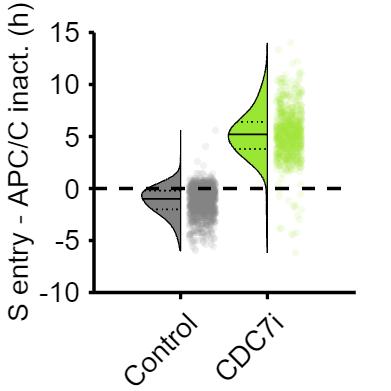


figure('Units', 'Inches', 'Position', [0, 0, 4 4])
h = violinPlot((ally),'groups',groups, 'showMM',6,'histOpt',1,'divFactor',.5,'histOri','left','widthDiv',[2 1],'color','black');

set(h{1},{'FaceColor'},cols)
hold on
jit = 0.3*rand(size(groups)) + .1;
scatter(groups+jit, (ally), 20,groupcol(groups,:),'filled','MarkerFaceAlpha',.1);
ylabel([ 'S entry - APC/C inact. (h)'])


xticklabels({'Control','CDC7i'})
ylim([-10 15])
yticks(-10:5:15)
 xtickangle(45)
 hline(0,'--k')
axis square
set(gca,'fontsize',17,'linewidth',2)


p=mediantest(ally(groups==1),ally(groups==2))

p = 2.8767e-294


% print_pdf(['fig_6a.pdf'])



6B

conds=[1 9 11 19];
timeGate = [-5 3];
S_ind = 3;
cols =  [.5 .5 .5;.6 .8 .1; 1 .5 .2; 0 .4 .6; .855 .384 1;0 0 1];
linetype = {'-','-','-','--'};

figure('unit','inches','position',[0 0 4 6]), hold on
POI_align = 1;
POI_cal = S_ind;
data_out = [];
frames_out = [];
for i=1:length(conds)
    data = S(conds(i));
   
 inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
        S(conds(i)).POI_drug_time(:,1) <= timeGate(2) & S(conds(i)).POI_drug_time(:,1) >= timeGate(1) &...
       S(conds(i)).goodCdk & (S(conds(i)).POI_drug_time(:,3) < 0 | isnan(S(conds(i)).POI(:,3)));
    if conds(i) >= 11
        inds = inds & S(conds(i)).apcGate;
    else
        inds = inds & S(conds(i)).apcGateAll;
    end
sum(inds)
    event = data.POI(:,POI_cal);
    start = data.POI(:,POI_align);
    ends = data.traceStats(:,6);

    
     y = event- start ;
    lost = ends  - start ;
    y = y/framesPerHr; %y = time of POI_cal relative to POI_align
    lost = lost/framesPerHr; % lost = last frame relative to POI_align
    censor = isnan(y); %if y isnan, censor = 1
    y(censor) = lost(censor);
    y_filt = y(inds);
    censor_filt = censor(inds);
    [f,x] = ecdf(y_filt,'Censoring',censor_filt);
    if isempty(f)
        f = 0;
        x = 0;
    end
    y_max = max(y_filt(censor_filt));
    if x(end) < y_max
        x(end+1) = y_max;
        f(end + 1) = f(end);
    end
    if f(end) == 1
        x(end+1) = 1000;
        f(end + 1) = f(end);
    end
     if x(1) ~= 0
        x0 = 0;
        f0 = 0;
        f = cat(1,f0,f);
        x = cat(1,x0,x);
     end 

    plot(x,f,'Color',cols(i,:),'LineStyle',linetype(i),'linewidth',2);
   
end

ans = 460

ans = 381

ans = 181

ans = 188

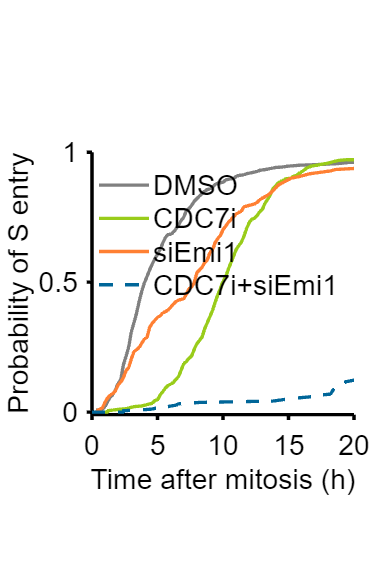


axis square
set(gca,'linewidth',2,'FontSize',17)
legend('DMSO','CDC7i','siEmi1','CDC7i+siEmi1','Box','off','Location','north','FontSize',17);
xlim([0 20]); 
xticks(0:5:20)
ylim([-.01 1]);
xlabel('Time after mitosis (h)')
ylabel('Probability of S entry')
hold on

% print_pdf(['fig_6b.pdf'])


6C

conds=[1 9 11 19];


colors = [.5 .5 .5;.6 .8 .1; 1 .5 .2;  .1 .4 1; 1 .5 .2;.1 .4 1;.6 .8 .1;0 0 1;.6 .1 .5;.7 .7 .2; 1 .5 .2; 0 .4 .6; .855 .384 1;0 0 1];
linetype = {'-','-','-','--'};
timeGate = [-5 3];

figure('unit','inches','position',[0 0 4 4])
hold on
axis square;
POI_align = 1;
for i=1:length(conds)
    c = conds(i);
    data = S(c);
       inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
        S(conds(i)).POI_drug_time(:,1) <= timeGate(2) & S(conds(i)).POI_drug_time(:,1) >= timeGate(1) &...
       S(conds(i)).goodCdk;
    if conds(i) >= 11
        inds = inds & S(conds(i)).apcGate;
    else
        inds = inds & S(conds(i)).apcGateAll;
    end
 sum(inds)


    ydata = data.cdk(inds,:);

    POI = data.POI(inds,POI_align) ;
    
    [frames, medSig, semCRL] =get_mean_trace(ydata,POI,1);
    shadedErrorBar((frames)/framesPerHr,medSig,2*semCRL,'lineProps',{'Color',colors(i,:),'LineWidth',1.5,'linestyle',linetype(i)});
end

ans = 498

ans = 406

ans = 187

ans = 195

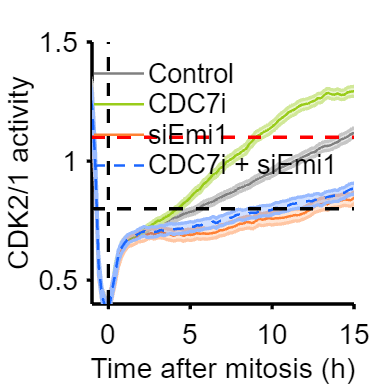


ylabel({'CDK2/1 activity'});xlabel('Time after mitosis (h)');
legend('Control','CDC7i','siEmi1','CDC7i + siEmi1','box','off','Location','north','fontsize',16);
set(gca,'linewidth',2,'fontsize',17)
xlim([-1 15]); 
ylim([.4 1.5]);
vline([0],'k--')
hline(.8,'k--')
hline(1.1,'r--')

% print_pdf(['fig_6c.pdf'])

6F

conds=[1 4];
colors = [.5 .5 .5; .9 0 .8];
POI_align = 3;
ally = [];
groups = [];
timeGate = [0 20];
clear cols
for i=1:length(conds)
    c = conds(i);
    data = S(c);
    inds = ~isnan(data.POI(:,POI_align)) &  ...
         data.POI_realtime(:,1) <= timeGate(2) & data.POI_realtime(:,1) >= timeGate(1) & data.apcExpressGate & data.goodCdk;
sum(inds)
    yvals = (data.POI_realtime(inds,3) - data.POI_realtime(inds,2));
    yvals = yvals(yvals < 200000 & yvals >= -200000);
    ally = [ally; yvals];
    groups = [groups; repmat(i,size(yvals))];
    meang1(i) = mean(yvals);
    length(yvals);
    cols(i,1) = ({colors(i,:)}');
    groupcol = repmat([colors([1:i],:)],1,1);
 

end

ans = 2833

ans = 310

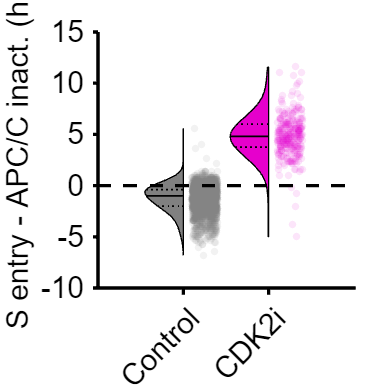


figure('Units', 'Inches', 'Position', [0, 0, 4 4])
h = violinPlot((ally),'groups',groups, 'showMM',6,'histOpt',1,'divFactor',.5,'histOri','left','widthDiv',[2 1],'color','black');

set(h{1},{'FaceColor'},cols)
hold on
jit = 0.3*rand(size(groups)) + .1;
scatter(groups+jit, (ally), 20,groupcol(groups,:),'filled','MarkerFaceAlpha',.1);
ylabel([ 'S entry - APC/C inact. (h)'])


xticklabels({'Control','CDK2i'})
ylim([-10 15])
yticks(-10:5:15)
 xtickangle(45)
 hline(0,'--k')
axis square
set(gca,'fontsize',18,'linewidth',2)



% print_pdf(['fig_6f.pdf'])
p=mediantest(ally(groups==1),ally(groups==2))

p = 1.6424e-79

6G

conds=[1 11 4 14];
timeGate = [-5 2];
cols =  [.5 .5 .5;1 .5 .2; 0 .4 .6; .855 .384 1;0 0 1];

linetype = {'-','-','--','--'};
S_ind = 3;


figure('unit','inches','position',[0 0 4 6]), hold on
POI_align = 1;
POI_cal = S_ind;
data_out = [];
frames_out = [];
for i=1:length(conds)
    data = S(conds(i));
  
 inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
        S(conds(i)).POI_drug_time(:,1) <= timeGate(2) & S(conds(i)).POI_drug_time(:,1) >= timeGate(1) &...
        S(conds(i)).apcExpressGate  & (S(conds(i)).POI_drug_time(:,3) < 0 | isnan(S(conds(i)).POI(:,3))) & S(conds(i)).goodCdk;
    if conds(i) >= 11
        inds = inds & S(conds(i)).apcGate;
    else
        inds = inds & S(conds(i)).apcGateAll;
    end
sum(inds)
    event = data.POI(:,POI_cal);
    start = data.POI(:,POI_align);
    ends = data.traceStats(:,6);

    
    
    y = event- start ;
    lost = ends  - start ;
    y = y/framesPerHr; %y = time of POI_cal relative to POI_align
    lost = lost/framesPerHr; % lost = last frame relative to POI_align
    censor = isnan(y); %if y isnan, censor = 1
    y(censor) = lost(censor);
    y_filt = y(inds);
    censor_filt = censor(inds);
    [f,x] = ecdf(y_filt,'Censoring',censor_filt);
    if isempty(f)
        f = 0;
        x = 0;
    end
    y_max = max(y_filt(censor_filt));
    if x(end) < y_max
        x(end+1) = y_max;
        f(end + 1) = f(end);
    end
    if f(end) == 1
        x(end+1) = 1000;
        f(end + 1) = f(end);
    end
     if x(1) ~= 0
        x0 = 0;
        f0 = 0;
        f = cat(1,f0,f);
        x = cat(1,x0,x);
     end 
    plot(x,f,'Color',cols(i,:),'LineStyle',linetype(i),'linewidth',2);
    
end

ans = 355

ans = 149

ans = 139

ans = 108

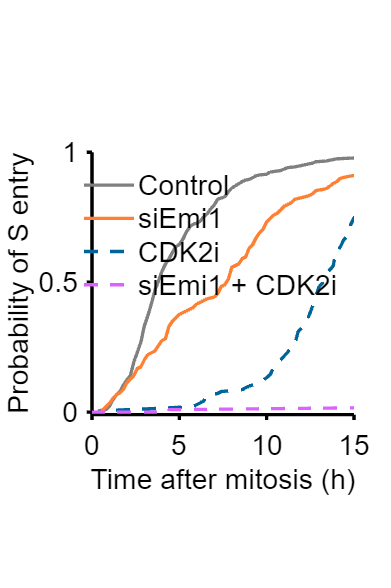


axis square
set(gca,'linewidth',2,'FontSize',17)
legend('Control','siEmi1','CDK2i','siEmi1 + CDK2i','Box','off','Location','north','FontSize',17);
xlim([0 15]); 
xticks(0:5:20)
ylim([-.01 1]);
xlabel('Time after mitosis (h)')
ylabel('Probability of S entry')

% print_pdf(['fig_6g.pdf'])

6H

conds=[1 11 7 17];
timeGate = [-5 2];
cols =  [.5 .5 .5; 1 .5 .2; 0 .4 .6; .855 .384 1;0 0 1];
linetype = {'-','-','--','--'};

figure('unit','inches','position',[0 0 4 6])
nexttile
hold on
POI_align = 1;
POI_cal = 3;
data_out = [];
frames_out = [];

for i=1:length(conds)
    data = S(conds(i));
 inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
        S(conds(i)).POI_drug_time(:,1) <= timeGate(2) & S(conds(i)).POI_drug_time(:,1) >= timeGate(1) &...
        S(conds(i)).apcExpressGate  & (S(conds(i)).POI_drug_time(:,3) < 0 | isnan(S(conds(i)).POI(:,3))) & S(conds(i)).goodCdk;
    if conds(i) >= 11
        inds = inds & S(conds(i)).apcGate;
    else
        inds = inds & S(conds(i)).apcGateAll;
    end
sum(inds)
    event = data.POI(:,POI_cal);
    start = data.POI(:,POI_align);
    ends = data.traceStats(:,6);

    
    y = event- start ;
    lost = ends  - start ;
    y = y/framesPerHr; %y = time of POI_cal relative to POI_align
    lost = lost/framesPerHr; % lost = last frame relative to POI_align
    censor = isnan(y); %if y isnan, censor = 1
    y(censor) = lost(censor);
    y_filt = y(inds);
    censor_filt = censor(inds);
    [f,x] = ecdf(y_filt,'Censoring',censor_filt);
     if isempty(f)
        f = 0;
        x = 0;
    end
    y_max = max(y_filt(censor_filt));
    if x(end) < y_max
        x(end+1) = y_max;
        f(end + 1) = f(end);
    end
    if f(end) == 1
        x(end+1) = 1000;
        f(end + 1) = f(end);
    end
     if x(1) ~= 0
        x0 = 0;
        f0 = 0;
        f = cat(1,f0,f);
        x = cat(1,x0,x);
     end 
    plot(x,f,'Color',cols(i,:),'LineStyle',linetype(i),'linewidth',2);
end

ans = 355

ans = 149

ans = 190

ans = 77

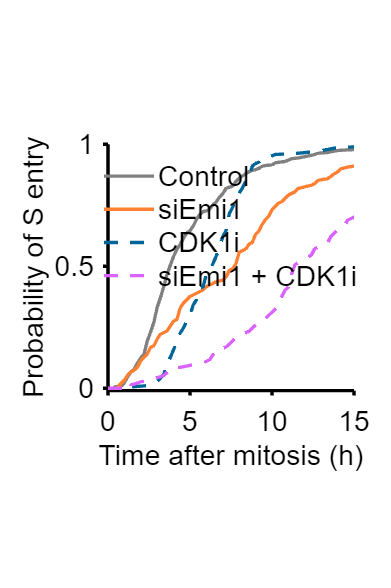



axis square
set(gca,'linewidth',2,'FontSize',17)
axis square
legend('Control','siEmi1','CDK1i','siEmi1 + CDK1i','Box','off','Location','north','FontSize',17);
xlim([0 15]); 
xticks(0:5:20)
ylim([-.01 1]);
xlabel('Time after mitosis (h)')
ylabel('Probability of S entry')
hold on

% print_pdf(['fig_6H.pdf'])


Threshold calc

conds=[1 9];


colors = [.1 .4 1;.6 .8 .1;0 0 1;.6 .1 .5;.7 .7 .2; 1 .5 .2; 0 .4 .6; .855 .384 1;0 0 1];
linetype = {'-','-','-','--'};
timeGate = [-5 3];

figure('unit','inches','position',[0 0 4 4])
hold on
axis square;
POI_align = 3;
for i=1:length(conds)
    c = conds(i);
    data = S(c);
         inds = ~isnan(S(conds(i)).POI(:,POI_align)) & S(conds(i)).apcGateAll&  ...
        S(conds(i)).POI_drug_time(:,1) <= timeGate(2) & S(conds(i)).POI_drug_time(:,1) >= timeGate(1) &...
       S(conds(i)).goodCdk;
 sum(inds)


    ydata = data.cdk(inds,:);

    POI = data.POI(inds,POI_align) ;
    
    [frames, medSig, semCRL] =get_mean_trace(ydata,POI,1);
    shadedErrorBar((frames)/framesPerHr,medSig,2*semCRL,'lineProps',{'Color',colors(i,:),'LineWidth',1.5,'linestyle',linetype(i)});
end

ans = 481

ans = 395

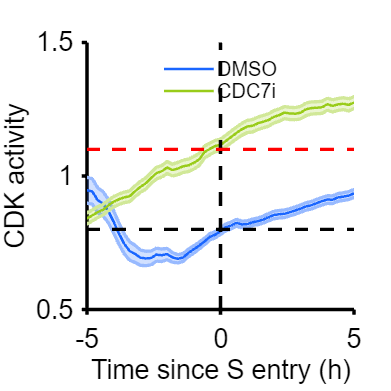


ylabel({'CDK activity'});xlabel('Time since S entry (h)');
legend('DMSO','CDC7i','box','off','Location','north','fontsize',12);

xlim([-5 5]); 
ylim([.5 1.5]);
vline([0],'k--')
hline(.8,'k--')
hline(1.1,'r--')

6I

conds=[ 14 17];


colors = [ .855 .384 1; 0 .4 .6;0 0 1];
linetype = {'--','-','-','--'};
timeGate = [-5 3];

figure('unit','inches','position',[0 0 4 4])
hold on
axis square;
POI_align = 1;
for i=1:length(conds)
    c = conds(i);
    data = S(c);
     inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
        S(conds(i)).POI_drug_time(:,1) <= timeGate(2) & S(conds(i)).POI_drug_time(:,1) >= timeGate(1) &...
       S(conds(i)).goodCdk;
    if conds(i) >= 11
        inds = inds & S(conds(i)).apcGate;
    else
        inds = inds & S(conds(i)).apcGateAll;
    end
 sum(inds)


    ydata = data.cdk(inds,:);

    POI = data.POI(inds,POI_align) ;
    
    [frames, medSig, semCRL] =get_mean_trace(ydata,POI,1);
    shadedErrorBar((frames)/framesPerHr,medSig,2*semCRL,'lineProps',{'Color',colors(i,:),'LineWidth',1.5,'linestyle',linetype(i)});
end

ans = 168

ans = 110

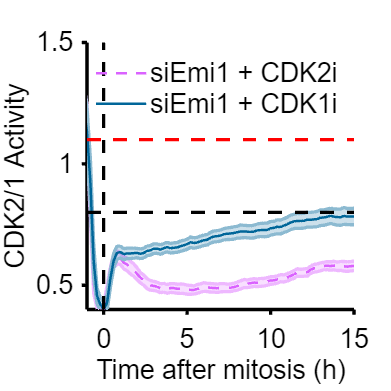


ylabel({'CDK2/1 Activity'});xlabel('Time after mitosis (h)');
legend('siEmi1 + CDK2i','siEmi1 + CDK1i','box','off','Location','north','fontsize',16);
set(gca,'linewidth',2,'fontsize',16)
xlim([-1 15]); 
ylim([.4 1.5]);
vline([0],'k--')
hline(.8,'k--')
hline(1.1,'r--')


% print_pdf(['fig_6i.pdf'])

S8C

conds=[1 9 11 19];
timeGate = [-5 3];
S_ind = 3;
cols =  [.5 .5 .5;.6 .8 .1; 1 .5 .2; 0 .4 .6; .855 .384 1;0 0 1];
linetype = {'-','-','-','--'};
% CRL activation post mitosis
figure('unit','inches','position',[0 0 4 6]), hold on
POI_align = 1;
POI_cal = 2;
data_out = [];
frames_out = [];
for i=1:length(conds)
    data = S(conds(i));
   
 inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
        S(conds(i)).POI_drug_time(:,1) <= timeGate(2) & S(conds(i)).POI_drug_time(:,1) >= timeGate(1) &...
       S(conds(i)).goodCdk & (S(conds(i)).POI_drug_time(:,3) < 0 | isnan(S(conds(i)).POI(:,3))) ;
    if conds(i) >= 11
        inds = inds & S(conds(i)).apcGate;
      
    else
        inds = inds & S(conds(i)).apcGateAll;
  
    end

sum(inds)
    event = data.POI(:,POI_cal);
    start = data.POI(:,POI_align);
    ends = data.traceStats(:,6);

    
    y = event- start ;
    lost = ends  - start ;
    y = y/framesPerHr; %y = time of POI_cal relative to POI_align
    lost = lost/framesPerHr; % lost = last frame relative to POI_align
    censor = isnan(y); %if y isnan, censor = 1
    y(censor) = lost(censor);
    y_filt = y(inds);
    censor_filt = censor(inds);
    [f,x] = ecdf(y_filt,'Censoring',censor_filt);
    if isempty(f)
        f = 0;
        x = 0;
    end
    y_max = max(y_filt(censor_filt));
    if x(end) < y_max
        x(end+1) = y_max;
        f(end + 1) = f(end);
    end
    if f(end) == 1
        x(end+1) = 1000;
        f(end + 1) = f(end);
    end
     if x(1) ~= 0
        x0 = 0;
        f0 = 0;
        f = cat(1,f0,f);
        x = cat(1,x0,x);
     end 
    plot(x,f,'Color',cols(i,:),'LineStyle',linetype(i),'linewidth',2);
    % plot(x,f); 

%     sum(inds)
end

ans = 460

ans = 381

ans = 181

ans = 188

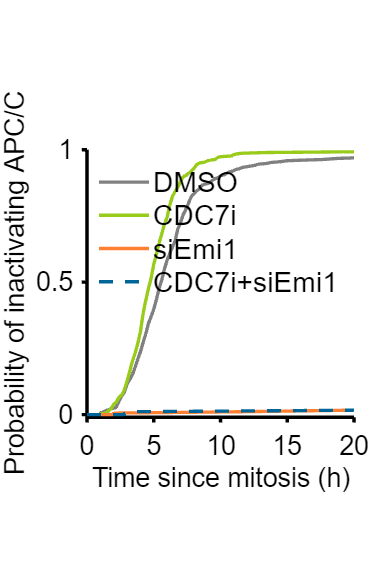

% legend(conditions(conds,1));
axis square
set(gca,'linewidth',2,'FontSize',16)
legend('DMSO','CDC7i','siEmi1','CDC7i+siEmi1','Box','off','Location','north','FontSize',17);
xlim([0 20]); 
xticks(0:5:20)
ylim([-.01 1]);
xlabel('Time since mitosis (h)')
ylabel('Probability of inactivating APC/C')
hold on

 % print_pdf(['fig_S8c.pdf'])

S8H

conds=[1 11 4 14];
timeGate = [-5 3];
S_ind = 3;
cols =  [.5 .5 .5; 1 .5 .2; 0 .4 .6; .855 .384 1;0 0 1];
linetype = {'-','-','-','--'};

figure('unit','inches','position',[0 0 4 6]), hold on
POI_align = 1;
POI_cal = 2;
data_out = [];
frames_out = [];
for i=1:length(conds)
    data = S(conds(i));
 
 inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
        S(conds(i)).POI_drug_time(:,1) <= timeGate(2) & S(conds(i)).POI_drug_time(:,1) >= timeGate(1) &...
       S(conds(i)).goodCdk & (S(conds(i)).POI_drug_time(:,3) < 0 | isnan(S(conds(i)).POI(:,3))) ;
    if conds(i) >= 11
        inds = inds & S(conds(i)).apcGate;
      
    else
        inds = inds & S(conds(i)).apcGateAll;
  
    end

sum(inds)
    event = data.POI(:,POI_cal);
    start = data.POI(:,POI_align);
    ends = data.traceStats(:,6);

    
    y = event- start ;
    lost = ends  - start ;
    y = y/framesPerHr; %y = time of POI_cal relative to POI_align
    lost = lost/framesPerHr; % lost = last frame relative to POI_align
    censor = isnan(y); %if y isnan, censor = 1
    y(censor) = lost(censor);
    y_filt = y(inds);
    censor_filt = censor(inds);
    [f,x] = ecdf(y_filt,'Censoring',censor_filt);
    if isempty(f)
        f = 0;
        x = 0;
    end
    y_max = max(y_filt(censor_filt));
    if x(end) < y_max
        x(end+1) = y_max;
        f(end + 1) = f(end);
    end
    if f(end) == 1
        x(end+1) = 1000;
        f(end + 1) = f(end);
    end
     if x(1) ~= 0
        x0 = 0;
        f0 = 0;
        f = cat(1,f0,f);
        x = cat(1,x0,x);
     end 
    plot(x,f,'Color',cols(i,:),'LineStyle',linetype(i),'linewidth',2);
   
end

ans = 460

ans = 181

ans = 210

ans = 156

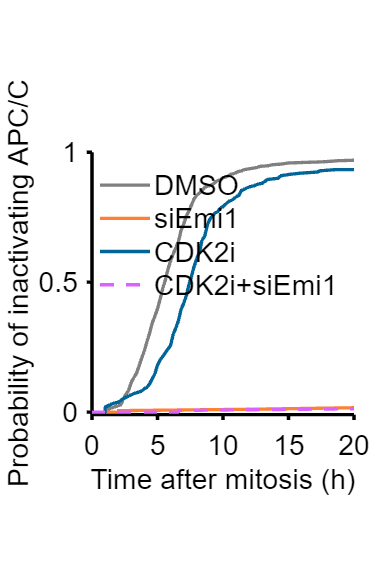


axis square
set(gca,'linewidth',2,'FontSize',17)
legend('DMSO','siEmi1','CDK2i','CDK2i+siEmi1','Box','off','Location','north','FontSize',17);
xlim([0 20]); 
xticks(0:5:20)
ylim([-.01 1]);
xlabel('Time after mitosis (h)')
ylabel('Probability of inactivating APC/C')
hold on

% print_pdf(['fig_S8h.pdf'])


S8I

conds=[1 11 7 17];

timeGate = [-5 3];
S_ind = 3;
cols =  [.5 .5 .5; 1 .5 .2; 0 .4 .6; .855 .384 1;0 0 1];
linetype = {'-','-','-','--'};

figure('unit','inches','position',[0 0 4 6]), hold on
POI_align = 1;
POI_cal = 2;
data_out = [];
frames_out = [];
for i=1:length(conds)
    data = S(conds(i));

 inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
        S(conds(i)).POI_drug_time(:,1) <= timeGate(2) & S(conds(i)).POI_drug_time(:,1) >= timeGate(1) &...
       S(conds(i)).goodCdk & (S(conds(i)).POI_drug_time(:,3) < 0 | isnan(S(conds(i)).POI(:,3))) ;
    if conds(i) >= 11
        inds = inds & S(conds(i)).apcGate;
      
    else
        inds = inds & S(conds(i)).apcGateAll;
  
    end

sum(inds)
    event = data.POI(:,POI_cal);
    start = data.POI(:,POI_align);
    ends = data.traceStats(:,6);

    
    y = event- start ;
    lost = ends  - start ;
    y = y/framesPerHr; %y = time of POI_cal relative to POI_align
    lost = lost/framesPerHr; % lost = last frame relative to POI_align
    censor = isnan(y); %if y isnan, censor = 1
    y(censor) = lost(censor);
    y_filt = y(inds);
    censor_filt = censor(inds);
    [f,x] = ecdf(y_filt,'Censoring',censor_filt);
    if isempty(f)
        f = 0;
        x = 0;
    end
    y_max = max(y_filt(censor_filt));
    if x(end) < y_max
        x(end+1) = y_max;
        f(end + 1) = f(end);
    end
    if f(end) == 1
        x(end+1) = 1000;
        f(end + 1) = f(end);
    end
     if x(1) ~= 0
        x0 = 0;
        f0 = 0;
        f = cat(1,f0,f);
        x = cat(1,x0,x);
     end 
    plot(x,f,'Color',cols(i,:),'LineStyle',linetype(i),'linewidth',2);
   
end

ans = 460

ans = 181

ans = 310

ans = 105

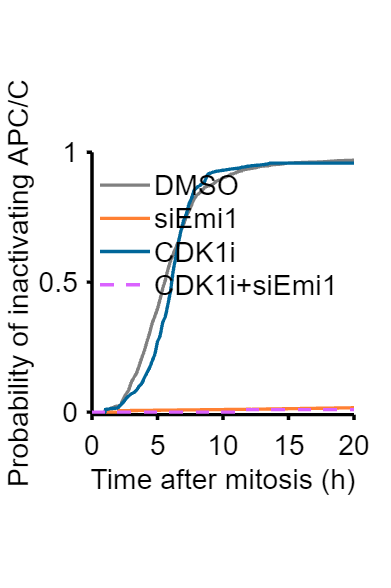


axis square
set(gca,'linewidth',2,'FontSize',17)
legend('DMSO','siEmi1','CDK1i','CDK1i+siEmi1','Box','off','Location','north','FontSize',17);
xlim([0 20]); 
xticks(0:5:20)
ylim([-.01 1]);
xlabel('Time after mitosis (h)')
ylabel('Probability of inactivating APC/C')
hold on

% print_pdf(['fig_S8i.pdf'])